clear all
close all
clc
datacursormode on;
set(gca,'Color','white')
[filename, pathname] = uigetfile({'*.jpg';'*.png'},'File Selector');
Completepath = strcat(pathname, filename);
I = imread(Completepath);
fprintf("%s\n",filename);

Bacterial_spot_1.JPG


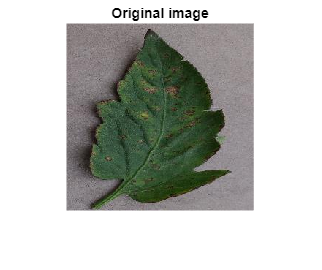

imshow(I),title('Original image')

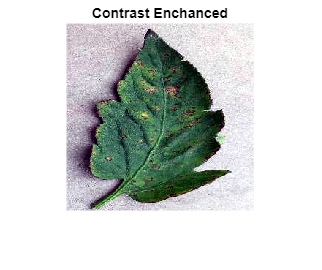

RGB = imresize(I,[512,512]);
I = imadjust(I,stretchlim(I));
imshow(I),title('Contrast Enchanced')

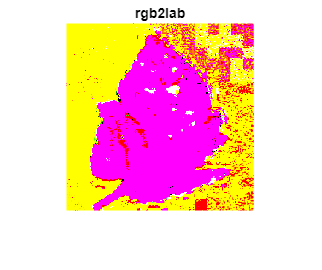

I_sRGB = rgb2lab(I);
%I_sRGB_Plane1 = I_sRGB(:,:,1);
%I_sRGB_Plane2 = I_sRGB(:,:,2);
%I_sRGB_Plane3 = I_sRGB(:,:,3);
imshow(I_sRGB),title('rgb2lab')

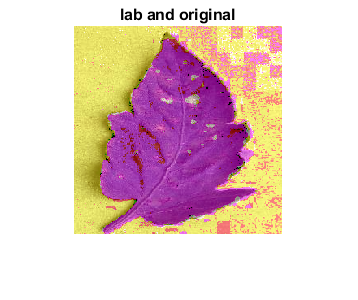


B = imfuse(I_sRGB,I,'blend','Scaling','joint');
imshow(B),title('lab and original')

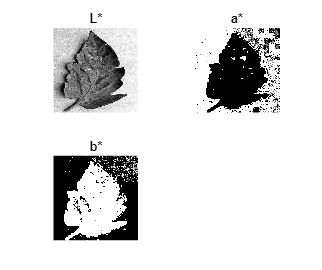


[L,a,b] = imsplit(I_sRGB);
a = imadjust(a);
b = imadjust(b);
subplot(2,2,1),imshow(L,[]),title('L*')
subplot(2,2,2),imshow(a,[]),title('a*')
subplot(2,2,3),imshow(b,[]),title('b*')

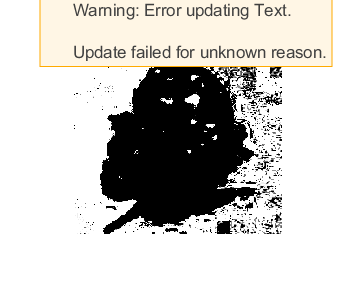

figure(2),imshow(a,[]),title('a*')

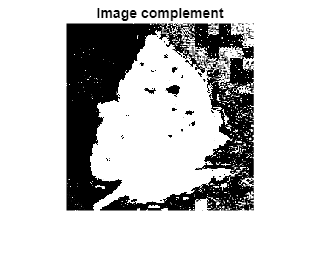

%histogram(b)

IBW1 = imcomplement(a);
imshow(IBW1),title('Image complement')

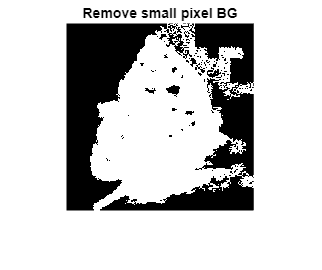


%IMask = IBW1 > 0;
%imshow(IMask),title('Manual remove pixel')

IBW2 = bwareaopen(IBW1,3500);
imshow(IBW2),title('Remove small pixel BG')

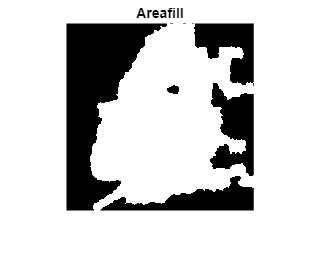


%ss = strel('square',2);
%IBW3 = imdilate(IBW2,ss);
%imshow(IBW3),title('test dilate')

se = strel('disk',4); %อยู่ระหว่าง 2-7 แล้วแต่ภาพที่ไม่ใช้ imfill เพราะมีบางภาพต้องคงรูไว้
IBW3 = imclose(IBW2,se);
imshow(IBW3),title('Areafill')

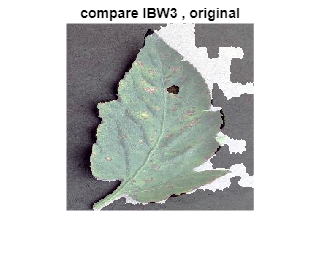


%IBW3 = imfill(IBW2,'holes');
%imshow(IBW3),title('Areafill')

C = imfuse(IBW3,I,'blend','Scaling','joint');
imshow(C),title('compare IBW3 , original')

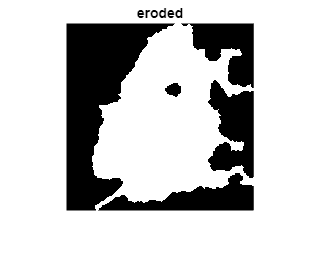



se = strel('diamond',3);        
erodedBW = imerode(IBW3,se);
imshow(erodedBW),title('eroded')

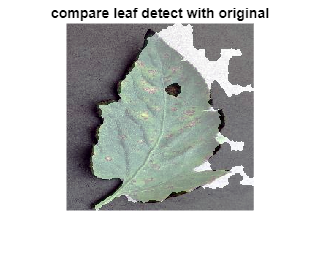

C2 = imfuse(erodedBW,I,'blend','Scaling','joint');
imshow(C2),title('compare leaf detect with original')

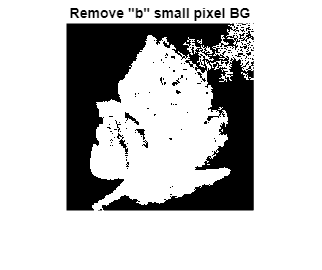


b = bwareaopen(b,3500);
imshow(b),title('Remove "b" small pixel BG')

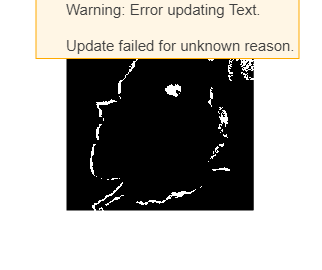


C3 = b - erodedBW;
imshow(C3),title('piece(b - eroded)')

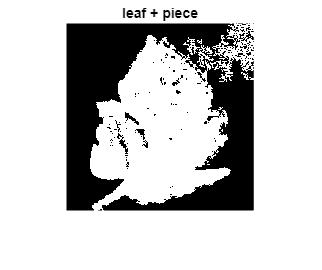


%C3 = edge(C3);
%imshow(C3),title('edge to edge')

C4 = erodedBW + C3;
imshow(C4),title('leaf + piece')

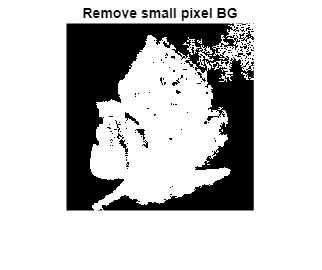


C4 = bwareaopen(C4,3500);
imshow(C4),title('Remove small pixel BG')

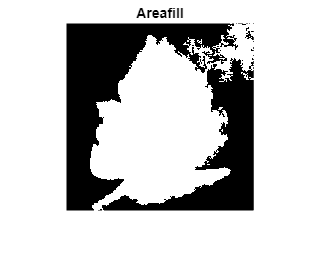


%se1 = strel('disk',4); %อยู่ระหว่าง 2-7 แล้วแต่ภาพที่ไม่ใช้ imfill เพราะมีบางภาพต้องคงรูไว้
%closeBW = imclose(C4,se1);
%imshow(closeBW),title('fill holes')

%se = strel('disk',2);
%C4 = imerode(closeBW,se);    for Bacterial_spot_1.JPG
%imshow(C4),title('eroded')

%C4 = imfill(C4,'holes');
%imshow(C4),title('Areafill')

C4 = imfill(C4,'holes');
imshow(C4),title('Areafill')

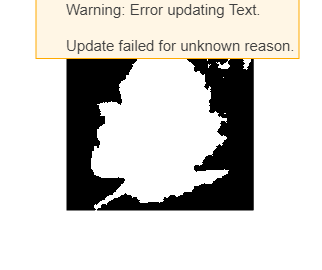


se = strel('disk',2);
erodedBW = imerode(C4,se);
imshow(erodedBW),title('eroded')

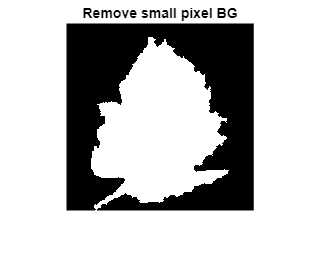


erodedBW = bwareaopen(erodedBW,3500);
imshow(erodedBW),title('Remove small pixel BG')

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.



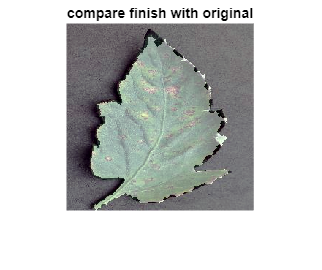


C5 = imfuse(erodedBW,I,'blend','Scaling','joint');
imshow(C5),title('compare finish with original')


%imwrite(erodedBW,'segmentation\SM_Bacterial_spot_4.JPG')

%stats = regionprops(IBW2,"Area");
%big_area = max([stats.Area]);

%IBW3 = bwareafilt(IBW2,[big_area big_area]);
%figure(3),imshow(IBW3),title('Areafill')


